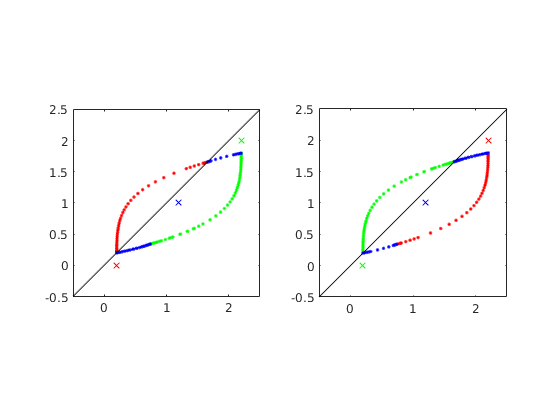

%% cycle 1

clear all
% close all

d = 0.2 ;
q_r = [ 0+d ; 0 ; 2+d ; 2 ] ;
q_g = [ 2+d ; 2 ; 0+d ; 0 ] ;
q_b = ( q_r + q_g ) / 2  ;
p = diag( [ 0.8 ; 0.2 ; 0.8 ; 0.2 ] ) ;

tspan = [0 25] ;
q0 = [ 0.2 ; 0.2 ; 2.2 ; 1.8 ] ;
% tspan = [0 50] ;
% q0 = [ 0.7 ; 0.7 ; 1.8 ; 1.4 ] ;

[t,q] = ode45(@(t, q) mces1(t, q, q_r, q_g, q_b, p), tspan, q0) ;

figure

plot_min = -0.5 ;
plot_max = 2.5 ;

subplot(121), box on, hold on
idx = q(:,1)<q(:,2); plot(q(idx,1), q(idx,2), "r.")
idx = q(:,3)<q(:,4); plot(q(idx,1), q(idx,2), "g.")
idx = (q(:,1)>q(:,2) & q(:,3)>q(:,4)); plot(q(idx,1), q(idx,2), "b.")
line([plot_min,plot_max] , [plot_min,plot_max], "color", "k")
% 
plot(q_r(1), q_r(2), "rx")
plot(q_g(1), q_g(2), "gx")
plot(q_b(1), q_b(2), "bx")
% 
axis equal
xlim([plot_min plot_max]) ;
ylim([plot_min plot_max]) ;
hold off


subplot(122), box on, hold on
idx = q(:,1)<q(:,2); plot(q(idx,3), q(idx,4), "r.")
idx = q(:,3)<q(:,4); plot(q(idx,3), q(idx,4), "g.")
idx = (q(:,1)>q(:,2) & q(:,3)>q(:,4)); plot(q(idx,3), q(idx,4), "b.")
line([plot_min,plot_max] , [plot_min,plot_max], "color", "k")
% 
plot(q_r(3), q_r(4), "rx")
plot(q_g(3), q_g(4), "gx")
plot(q_b(3), q_b(4), "bx")
% 
axis equal
xlim([plot_min plot_max]) ;
ylim([plot_min plot_max]) ;
hold off

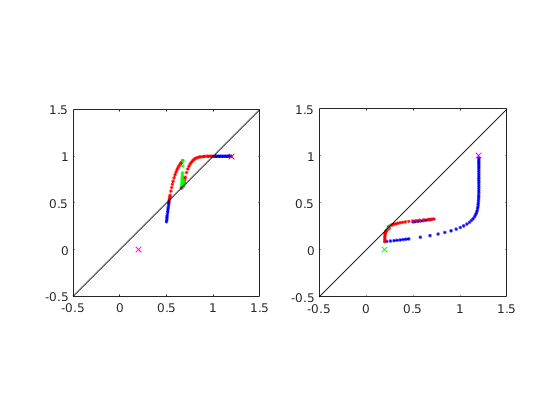

%% cycle 2

clear all
% close all

d = 0.2 ;
q_1 = [ 1+d ; 1 ; 1+d ; 1 ] ;
q_2 = [ 1+d ; 1 ; 0+d ; 0 ] ;
q_3 = [ 0+d ; 0 ; 0+d ; 0 ] ;
q_4 = [ 0+d ; 0 ; 1+d ; 1 ] ;
p = diag( [ 0.1 ; 0.9 ; 0.9 ; 0.1 ] ) ;

tspan = [0 50] ;
q0 = [ 0.5 ; 0.3 ; 0.5 ; 0.3 ] ;

[t,q] = ode45(@(t, q) mces2(t, q, q_1, q_2, q_3, q_4, p), tspan, q0) ;

figure

plot_min = -0.5 ;
plot_max = 1.5 ;

subplot(121), box on, hold on
idx = (q(:,1)>=q(:,2) & q(:,3)>=q(:,4)); plot(q(idx,1), q(idx,2), "b.")
idx = (q(:,1)<=q(:,2) & q(:,3)>=q(:,4)); plot(q(idx,1), q(idx,2), "r.")
idx = (q(:,1)<=q(:,2) & q(:,3)<=q(:,4)); plot(q(idx,1), q(idx,2), "g.")
idx = (q(:,1)>=q(:,2) & q(:,3)<=q(:,4)); plot(q(idx,1), q(idx,2), "m.")
line([plot_min,plot_max] , [plot_min,plot_max], "color", "k")
% 
plot(q_1(1), q_1(2), "bx")
plot(q_2(1), q_2(2), "rx")
plot(q_3(1), q_3(2), "gx")
plot(q_4(1), q_4(2), "mx")
% 
axis equal
xlim([plot_min plot_max]) ;
ylim([plot_min plot_max]) ;
hold off

subplot(122), box on, hold on
idx = (q(:,1)>=q(:,2) & q(:,3)>=q(:,4)); plot(q(idx,3), q(idx,4), "b.")
idx = (q(:,1)<=q(:,2) & q(:,3)>=q(:,4)); plot(q(idx,3), q(idx,4), "r.")
idx = (q(:,1)<=q(:,2) & q(:,3)<=q(:,4)); plot(q(idx,3), q(idx,4), "g.")
idx = (q(:,1)>=q(:,2) & q(:,3)<=q(:,4)); plot(q(idx,3), q(idx,4), "m.")
line([plot_min,plot_max] , [plot_min,plot_max], "color", "k")
% 
plot(q_1(3), q_1(4), "bx")
plot(q_2(3), q_2(4), "rx")
plot(q_3(3), q_3(4), "gx")
plot(q_4(3), q_4(4), "mx")
% 
axis equal
xlim([plot_min plot_max]) ;
ylim([plot_min plot_max]) ;
hold off

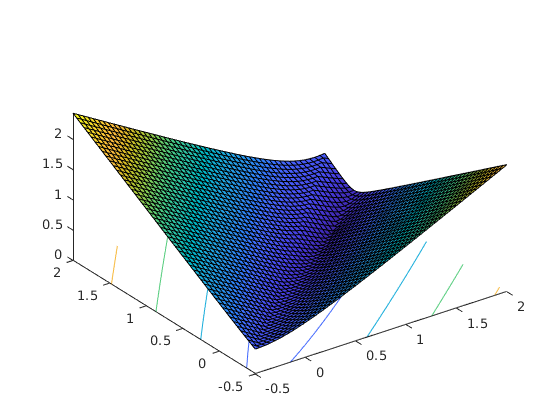

clear all
% close all

g = 0.8 ;
d = 0.3 ;
%q_1 = [ 1+d ; 1 ] ;
%q_2 = [ 0+d ; 0 ] ;
q_1 = [ 1.5 ; 1.2 ] ;
q_2 = [ 0.3 ; 0 ] ;
p1 = diag( [ 0.1 ; 0.9 ] ) ;
p2 = diag( [ 0.9 ; 0.1 ] ) ;

I = eye(2) ;
P1 = [1 0 ; 1 0] ;
P2 = [0 1 ; 0 1] ;


% comute Lyapunov surface
xmin = -0.5 ;
xmax = 2 ;
stp = 0.05 ;
[X,Y] = meshgrid(xmin:stp:xmax, xmin:stp:xmax) ;

X1 = triu(X) ;
Y1 = triu(Y) ;
V1 = triu(reshape(vecnorm((I-g*P1)*(q_1 - [X1(:)' ; Y1(:)'])), size(X, 1), size(X, 2))) ;

X2 = tril(X) ;
Y2 = tril(Y) ;
V2 = tril(reshape(vecnorm((I-g*P2)*(q_2 - [X2(:)' ; Y2(:)'])), size(X, 1), size(X, 2))) ;

V = triu(V1, 1) + V2 ;

figure
hold on
% contour(X, Y, V)
surfc(X, Y, V)
view(10, 10)
hold off

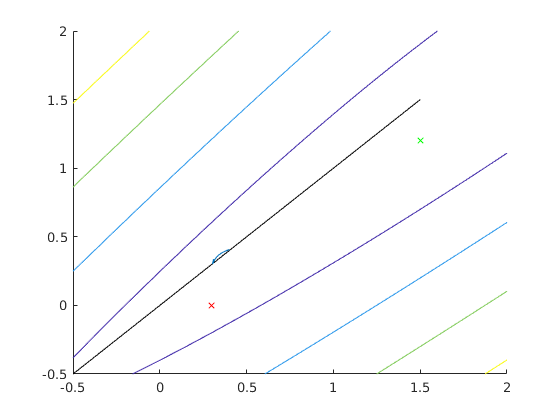


tspan = [0 50] ;
q0 = [ 0.4 ; 0.4 ] ;

[t,q] = ode45(@(t, q) mces3(t, q, q_1, q_2, p1, p2), tspan, q0) ;

figure
hold on
plot_min = -0.5 ;
plot_max = 1.5 ;
contour(X, Y, V)
line([plot_min,plot_max] , [plot_min,plot_max], "color", "k")

plot(q(:,1), q(:,2))

plot(q_1(1), q_1(2), 'gx')
plot(q_2(1), q_2(2), 'rx')
hold off

clear all
% close all

g = 0.6 ;
d = 0.3 ;

eps = 0.01 ;

q_1 = [ 1.5 ; 1.2 ] ;
q_2 = [ 0.3 ; 0 ] ;
p1 = diag( [ 0.1 ; 0.9 ] ) ;
p2 = diag( [ 0.9 ; 0.1 ] ) ;

I = eye(2) ;
P1 = [1 0 ; 1 0] ;
P2 = [0 1 ; 0 1] ;

A1 = -(I-g*P1)*p1*(I-g*P1)^-1 ;
A2 = -(I-g*P2)*p2*(I-g*P2)^-1 ;

cvx_begin sdp
variable P(2,2) symmetric
A1'*P + P*A1 <= -eps*eye(2)
A2'*P + P*A2 <= -eps*eye(2)
P >= eps*eye(2)
cvx_end

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|6.4e+01|2.4e+01|6.0e+02|-1.387779e-17  0.000000e+00| 0:0:00| chol  1  1 
 1|0.924|0.945|4.9e+00|1.4e+00|4.0e+01|-2.696682e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.754|2.3e-06|3.5e-01|6.6e+00|-4.730339e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.918|1.7e-05|3.0e-02|1.4e-01|-5.407368e-01  0.000000e+0


P

P =    NaN   NaN
   NaN   NaN


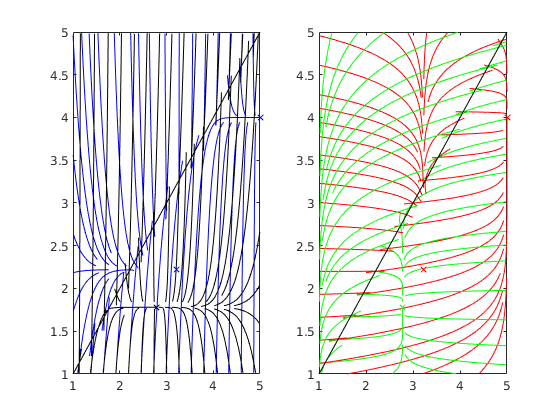

clear all

g = 0.8 ;
r = [ 1 0 1 0 ] ;
p = diag( [ 0.1 ; 0.9 ; 0.9 ; 0.1] ) ;

q1 = [5 4 5 4]' ;
q2 = [3.22 2.22 2.78 1.78]' ;
q3 = [2.78 1.78 3.22 2.22]' ;
q4 = [1 0 1 0]' ;

P1 = [ 0 0 1 0 ; 0 0 1 0 ; 1 0 0 0 ; 1 0 0 0 ] ;
P2 = [ 0 0 1 0 ; 0 0 1 0 ; 0 1 0 0 ; 0 1 0 0 ] ;
P3 = [ 0 0 0 1 ; 0 0 0 1 ; 1 0 0 0 ; 1 0 0 0 ] ;
P4 = [ 0 0 0 1 ; 0 0 0 1 ; 0 1 0 0 ; 0 1 0 0 ] ;

qmin = 1 ;
stp = 0.1 ;
qmax = 5 ;

[X, Y] = meshgrid(qmin:stp:qmax, qmin:stp:qmax) ;

U1v = p*(q1 - [X(:) Y(:) X(:) Y(:)]') ;
U1 = reshape(U1v', [size(X,1), size(X,2), 4]) ; 

U2v = p*(q2 - [X(:) Y(:) X(:) Y(:)]') ;
U2 = reshape(U2v', [size(X,1), size(X,2), 4]) ; 

U3v = p*(q3 - [X(:) Y(:) X(:) Y(:)]') ;
U3 = reshape(U3v', [size(X,1), size(X,2), 4]) ; 

U4v = p*(q4 - [X(:) Y(:) X(:) Y(:)]') ;
U4 = reshape(U4v', [size(X,1), size(X,2), 4]) ; 




figure

subplot(121), box on, hold on
u1 = streamslice(X, Y, triu(U1(:, :, 1)), triu(U1(:, :, 2)), 0.4, 'noarrows') ;
set(u1, 'color', 'b')
u2 = streamslice(X, Y, tril(U2(:, :, 1)), tril(U2(:, :, 2)), 0.4, 'noarrows') ;
set(u2, 'color', 'b')
u3 = streamslice(X, Y, triu(U3(:, :, 1)), triu(U3(:, :, 2)), 0.4, 'noarrows') ;
set(u3, 'color', 'k')
u4 = streamslice(X, Y, tril(U4(:, :, 1)), tril(U4(:, :, 2)), 0.4, 'noarrows') ;
set(u4, 'color', 'k')
plot(q1(1), q1(2), 'bx')
plot(q2(1), q2(2), 'bx')
plot(q3(1), q3(2), 'kx')
plot(q4(1), q4(2), 'kx')
line([qmin, qmax], [qmin, qmax], 'color', 'k')
xlim([qmin qmax])
ylim([qmin qmax])
hold off
% axis equal

subplot(122), box on, hold on
u1 = streamslice(X, Y, triu(U1(:, :, 3)), triu(U1(:, :, 4)), 0.4, 'noarrows') ;
set(u1, 'color', 'r')
u2 = streamslice(X, Y, triu(U2(:, :, 3)), triu(U2(:, :, 4)), 0.4, 'noarrows') ;
set(u2, 'color', 'g')
u3 = streamslice(X, Y, tril(U3(:, :, 3)), tril(U3(:, :, 4)), 0.4, 'noarrows') ;
set(u3, 'color', 'r')
u4 = streamslice(X, Y, tril(U4(:, :, 3)), tril(U4(:, :, 4)), 0.4, 'noarrows') ;
set(u4, 'color', 'g')
plot(q1(3), q1(4), 'rx')
plot(q2(3), q2(4), 'gx')
plot(q3(3), q3(4), 'rx')
plot(q4(3), q4(4), 'gx')
line([qmin, qmax], [qmin, qmax], 'color', 'k')
xlim([qmin qmax])
ylim([qmin qmax])
hold off

% axis equal



clear all
rng(13)

T = [0 0 1 1 ; 1 1 0 0] ;
I = eye(4) ;

P1 = [1 0 ; 0 0 ; 0 1 ; 0 0] ;
P2 = [0 0 ; 1 0 ; 0 1 ; 0 0] ;
P3 = [0 0 ; 1 0 ; 0 0 ; 0 1] ;
P4 = [1 0 ; 0 0 ; 0 0 ; 0 1] ;

g = 0.95 ;
p = diag([0.6, 0.2, 0.2, 0.6]) ;
a = [0.3, 0.1, 0.3, 0.3] ;

A1 = -(I-g*T'*P1')*p*(I-g*T'*P1')^-1 ;
A2 = -(I-g*T'*P2')*p*(I-g*T'*P2')^-1 ;
A3 = -(I-g*T'*P3')*p*(I-g*T'*P3')^-1 ;
A4 = -(I-g*T'*P4')*p*(I-g*T'*P4')^-1 ;

A = a(1)*A1 + a(2)*A2 + a(3)*A3 + a(4)*A4 ;
eig( A )

ans =   -0.4000 + 2.2218i
  -0.4000 - 2.2218i
  -0.9087 + 0.0000i
   0.1087 + 0.0000i


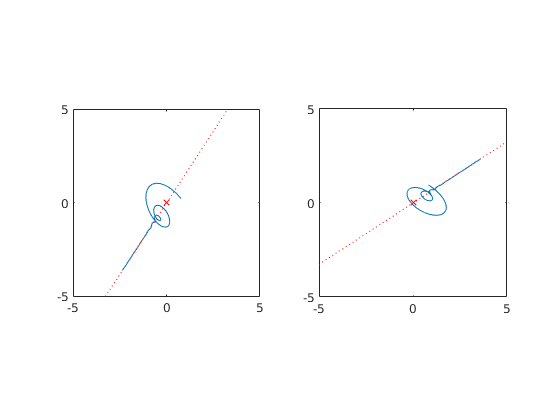

% x0 = .5*[1 ; 1 ; 1 ; 1] ;
x0 = rand(4,1) ;
dt = 0.1 ;
T = 20 ;
tspan = 0:dt:T ;

M = A ;
[t,x] = ode45(@(t, x) M*x, tspan, x0) ;
[V,D] = eig(M) ;
[~, i] = max(real(diag(D))) ;

figure

plot_min = -5 ; plot_max = -plot_min ;

subplot(121), box on, hold on
plot(x(:,1), x(:,2))
plot([plot_min, plot_max], V(2,i)/V(1,i)*[plot_min, plot_max], 'r:')
plot([0], [0], "rx")
axis equal
xlim([plot_min plot_max]) ;
ylim([plot_min plot_max]) ;
hold off

subplot(122), box on, hold on
plot(x(:,3), x(:,4))
plot([0], [0], "rx")
plot([plot_min, plot_max], V(4,i)/V(3,i)*[plot_min, plot_max], 'r:')
axis equal
xlim([plot_min plot_max]) ;
ylim([plot_min plot_max]) ;
hold off

clear all
% close all

d = 0.3 ;
q_1 = [ 3 ; 4 ] ;
q_2 = [ 1 ; 0 ] ;
p1 = diag( [ 0.9 ; 0.1] ) ;
p2 = p1 ;

dt = 0.05 ;
T = 21.88 ;
tspan = 0:dt:T ;
% tspan = exp(0:dt:log(T/2)) ;
q0 = [ 1 ; 1 ] ;

[t,q] = ode45(@(t, q) mces3(t, q, q_1, q_2, p1, p2), tspan, q0) ;

sum( ((q(:,1)>=q(:,2)) * q_1' + (q(:,1)<q(:,2)) * q_2' - q)*dt )

ans =     0.0734    0.1882


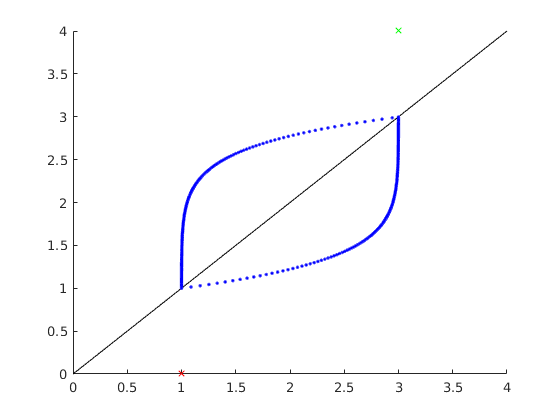


figure
hold on
plot_min = 0 ;
plot_max = 4 ;
line([plot_min,plot_max] , [plot_min,plot_max], "color", "k")

plot(q(:,1), q(:,2), 'b.')

plot(q_1(1), q_1(2), 'gx')
plot(q_2(1), q_2(2), 'rx')
hold off

% consider one dimension at the time

ds = 0.1 ;

% new_tspan = [0] ;
% for i = 1:length(t)
%     delta = ds/ ;
%     new_tspan(end+1) =  ;
% end



clear all

eps = 0.3 ;
q1 = [1+eps ; 1] ;
q2 = [0+eps ; 0] ;
p = diag( [0.2 ; 0.8] ) ;

m = -0.5 ;
stp = 0.05 ;
M = 1.5 ;
[X, Y] = meshgrid(m:stp:M, m:stp:M) ;
[nrow, ncol] = size(X) ;

V1 = p * (q1 - [X(:) Y(:)]') ;
V1x = reshape(V1(1,:), [nrow, ncol]) ;
V1y = reshape(V1(2,:), [nrow, ncol]) ;

V2 = p * (q2 - [X(:) Y(:)]') ;
V2x = reshape(V2(1,:), [nrow, ncol]) ;
V2y = reshape(V2(2,:), [nrow, ncol]) ;

U = V1 ./ vecnorm(V1) + V2 ./ vecnorm(V2) ;
Ux = reshape(U(1,:), [nrow, ncol]) ;
Uy = reshape(U(2,:), [nrow, ncol]) ;

% all( sum(U.*V1) >= 0)
% all( sum(U.*V2) >= 0)
W = sum(V1 .* U) ;
idx = find(W<=0) ;
Z = [X(:) Y(:)];
Z(idx, :)

ans =     0.3500    0.0500
    0.4000    0.1000
    0.4500    0.1500
    0.5000    0.2000
    0.6500    0.3500
    0.7000    0.4000
    0.8500    0.5500
    0.9000    0.6000
    1.0000    0.7000
    1.0500    0.7500


W(idx)

ans = 	1.0e+-16 *

   -0.5274   -0.5995   -0.1416   -0.5773   -0.3247   -0.4330   -0.0500   -0.3109         0   -0.2359         0         0


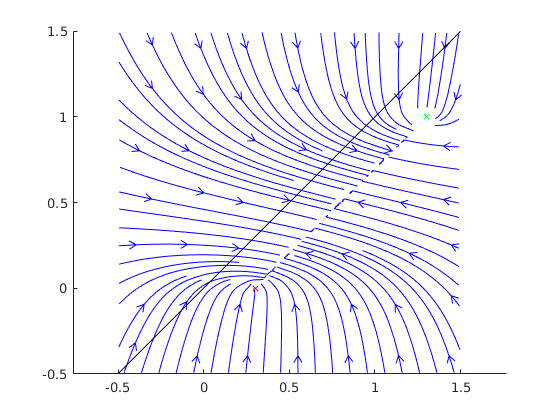

figure
hold on
% v1 = streamslice(X, Y, V1x, V1y) ;
% set(v1, 'color', 'g')
% v2 = streamslice(X, Y, V2x, V2y) ;
% set(v2, 'color', 'r')
u = streamslice(X, Y, Ux, Uy) ;
% u = streamline(X, Y, U(1,:), U(2,:)) ;
set(u, 'color', 'b')
plot(q1(1), q1(2), 'gx')
plot(q2(1), q2(2), 'rx')
line([m, M], [m, M], 'color', 'k')
hold off
axis equal

clear all

eps = 0.2 ;
q1 = [1+eps ; 1] ;
q2 = [2+eps ; 2] ;
q3 = [3+eps ; 3] ;
q4 = [4+eps ; 4] ;
p = diag( [0.8 ; 0.2] ) ;

m = -0 ;
stp = 0.1 ;
M = 5 ;
[X, Y] = meshgrid(m:stp:M, m:stp:M) ;
[nrow, ncol] = size(X) ;

V1 = p * (q1 - [X(:) Y(:)]') ;
V1x = reshape(V1(1,:), [nrow, ncol]) ;
V1y = reshape(V1(2,:), [nrow, ncol]) ;

V2 = p * (q2 - [X(:) Y(:)]') ;
V2x = reshape(V2(1,:), [nrow, ncol]) ;
V2y = reshape(V2(2,:), [nrow, ncol]) ;

V3 = p * (q3 - [X(:) Y(:)]') ;
V3x = reshape(V3(1,:), [nrow, ncol]) ;
V3y = reshape(V3(2,:), [nrow, ncol]) ;

V4 = p * (q4 - [X(:) Y(:)]') ;
V4x = reshape(V4(1,:), [nrow, ncol]) ;
V4y = reshape(V4(2,:), [nrow, ncol]) ;

U = V1 ./ vecnorm(V1) + V2 ./ vecnorm(V2) + V3 ./ vecnorm(V3) + V4 ./ vecnorm(V4) ;
Ux = reshape(U(1,:), [nrow, ncol]) ;
Uy = reshape(U(2,:), [nrow, ncol]) ;

% all( sum(U.*V1) >= 0)
% all( sum(U.*V2) >= 0)
W = sum(V1 .* U) ;
idx = find(W<=0) ;
Z = [X(:) Y(:)];
Z(idx, :)

ans =     1.2000    1.0000
    1.2500    0.7500
    1.2500    0.8000
    1.2500    0.8500
    1.2500    0.9000
    1.2500    0.9500
    1.2500    1.0000
    1.2500    1.0500
    1.2500    1.1000
    1.2500    1.1500


W(idx)

ans =    -0.0000   -0.0082   -0.0253   -0.0411   -0.0552   -0.0670   -0.0762   -0.0825   -0.0860   -0.0874   -0.0869   -0.0852   -0.0823   -0.0786   -0.0741   -0.0689   -0.0630   -0.0566   -0.0495   -0.0419   -0.0338   -0.0251   -0.0159   -0.0062   -0.0197   -0.0389   -0.0572   -0.0746   -0.0909   -0.1060   -0.1198   -0.1321   -0.1428   -0.1519   -0.1593   -0.1649   -0.1690   -0.1715   -0.1727   -0.1727   -0.1715   -0.1693   -0.1661   -0.1621   -0.1572   -0.1516   -0.1453   -0.1383   -0.1306   -0.1223


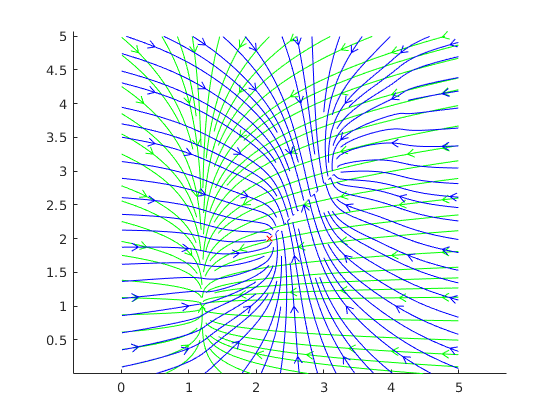

figure
hold on
v1 = streamslice(X, Y, V1x, V1y) ;
set(v1, 'color', 'g')
% v2 = streamslice(X, Y, V2x, V2y) ;
% set(v2, 'color', 'r')
u = streamslice(X, Y, Ux, Uy) ;
% u = streamline(X, Y, U(1,:), U(2,:)) ;
set(u, 'color', 'b')
plot(q1(1), q1(2), 'gx')
plot(q2(1), q2(2), 'rx')
hold off
axis equal

function dqdt = mces1(t, q, q_r, q_g, q_b, p)
    
    if q(1) < q(2)
        q_pol = q_r ;
    elseif q(3) < q(4)
        q_pol = q_g ;
    elseif q(1) >= q(2) & q(3) >= q(4)
%     else
        q_pol = q_b ;
    end

    dqdt = p * (q_pol - q) ;
end


function dqdt = mces2(t, q, q_1, q_2, q_3, q_4, p)
    
    if q(1) >= q(2) & q(3) >= q(4)
        q_pol = q_1 ;
    elseif q(1) <= q(2) & q(3) >= q(4)
        q_pol = q_2 ;
    elseif q(1) <= q(2) & q(3) <= q(4)
        q_pol = q_3 ;
    elseif q(1) >= q(2) & q(3) <= q(4)
        q_pol = q_4 ;
    end

    dqdt = p * (q_pol - q) ;
end


function dqdt = mces3(t, q, q_1, q_2, p1, p2)
    
    if q(1) >= q(2)
        dqdt = p1 * (q_1 - q) ;
    else
        dqdt = p2 * (q_2 - q) ;
    end
end


function dqdt = mces_vec(q, q_r, q_g, q_b, p)
    
    if q(1) < q(2)
        q_pol = q_r ;
    elseif q(3) < q(4)
        q_pol = q_g ;
    elseif q(1) >= q(2) & q(3) >= q(4)
%     else
        q_pol = q_b ;
    end

    dqdt = p * (q_pol - q) ;
end